# **Case 2: Krylov subspace methods**

### Question01 - Basics: Arnoldi iteration.

% Author： Guangxin Kuang

% Construct a sample matrix from the question.
matrixA = [3 8 7 3 3 7 2 3 4 8;
           5 4 1 6 9 8 3 7 1 9;
           3 6 9 4 8 6 5 6 6 6;
           5 3 4 7 4 9 2 3 5 1;
           4 4 2 1 7 4 2 2 4 5;
           4 2 8 6 6 5 2 1 1 2;
           2 8 9 5 2 9 4 7 3 3;
           9 3 2 2 7 3 4 8 7 7;
           9 1 9 3 3 1 2 7 7 1;
           9 3 2 2 6 4 4 7 3 5];

initialVector = rand(10, 1);
numArnoldiSteps = 9; 

% Perform Arnoldi iteration and print matrixes
[orthogonalBasis, hessenbergMatrix] = arnoldi(matrixA, initialVector, numArnoldiSteps);
fprintf('The orthogonalBasis is:\n');

The orthogonalBasis is:


disp(orthogonalBasis);

    0.1684    0.4675   -0.3244    0.3036    0.0378   -0.0447    0.2458   -0.6034    0.0673    0.3509
    0.4147   -0.2131    0.5346    0.6251   -0.2160   -0.0854   -0.0097   -0.1034    0.1400   -0.1473
    0.3997    0.1386   -0.2476   -0.1000   -0.0185    0.5556   -0.4865   -0.0694    0.3393   -0.2898
    0.0992    0.4686   -0.0591   -0.1510   -0.7226   -0.3293    0.0290    0.2969    0.1260   -0.0940
    0.0726    0.3747    0.0133    0.1535    0.1422    0.0371   -0.0121   -0.0128   -0.7186   -0.5407
    0.3041   -0.0995    0.2126   -0.4138   -0.0848   -0.3024   -0.4977   -0.3714   -0.3387    0.2867
    0.5856   -0.3108   -0.5317    0.0796    0.1563   -0.2865    0.1346    0.3543   -0.1331    0.0597
    0.2077    0.3224    0.2966    0.0664    0.1052    0.3914   -0.0074    0.4716   -0.1946    0.5796
    0.3571   -0.0715    0.2395   -0.5067   -0.0505    0.2464    0.6587   -0.1809    0.0048   -0.1527
    0.1366    0.3759    0.2661   -0.1481    0.6033   -0.4298   -0.0446    0.1159    0.3978 

fprintf('The hessenbergMatrix is:\n');

The hessenbergMatrix is:


disp(hessenbergMatrix);

   35.7457   21.6820    7.0394   -1.6618   -0.1963    0.3720   -5.7265   -3.1087   -5.1766
   16.1704   10.4337    4.2167   -0.7826    2.6422   -2.0549    2.1417   -4.9193   -3.4105
         0    9.1273   -2.2315    1.1176    3.6830   -1.9800    4.9377   -0.9654   -4.7498
         0         0    6.4343    1.1026    3.7546   -7.5365   -1.8065    2.0992   -1.8033
         0         0         0    3.7817    5.4318    1.3637    2.3653    0.8842    0.7713
         0         0         0         0    3.9938    3.5850    4.3527    1.3221    0.8248
         0         0         0         0         0    3.5774    2.9699   -1.4156    3.0202
         0         0         0         0         0         0    3.5876    0.6729   -2.9262
         0         0         0         0         0         0         0    1.6148    0.3273
         0         0         0         0         0         0         0         0    2.4231




% Print the 9th orthonormal basis vector
if size(orthogonalBasis, 2) >= 9
    Q9 = orthogonalBasis(:, 9);
    fprintf('The 9th orthonormal basis vector Q9 is:\n');
    disp(Q9);
    % Check if q9 is normalized (its norm should be 1)
    norm_Q9 = norm(Q9);
    fprintf('Norm of the 9th orthonormal basis vector: %e\n', norm_Q9);
else
    disp('The iteration terminated early; not enough basis vectors were generated.\n');
end

The 9th orthonormal basis vector Q9 is:


    0.0673
    0.1400
    0.3393
    0.1260
   -0.7186
   -0.3387
   -0.1331
   -0.1946
    0.0048
    0.3978



Norm of the 9th orthonormal basis vector: 1.000000e+00



% -------------------------------Local Functions-----------------------------
function [orthogonalBasis, hessenbergMatrix] = arnoldi(matrixA, initialVector, numArnoldiSteps)
%   Inputs:
%       matrixA          - An n x n matrix
%       initialVector    - An n x 1 initial vector
%       numArnoldiSteps  - The number of Arnoldi iterations
%
%   Outputs:
%       orthogonalBasis  - An n x (numArnoldiSteps+1) orthonormal matrix
%       hessenbergMatrix - A (numArnoldiSteps+1) x numArnoldiSteps upper Hessenberg matrix

n = length(initialVector);                    
orthogonalBasis = zeros(n, numArnoldiSteps+1);
hessenbergMatrix = zeros(numArnoldiSteps+1, numArnoldiSteps);

% Normalize the initial vector to obtain the first orthonormal basis vector
orthogonalBasis(:, 1) = initialVector / norm(initialVector);
tolerance = 1e-12;  % Tolerance to detect breakdown

for k = 1:numArnoldiSteps
    currentVector = matrixA * orthogonalBasis(:, k);  % Compute the new vector
    
    % Orthogonalize currentVector using the modified Gram-Schmidt process
    for j = 1:k
        hessenbergMatrix(j, k) = orthogonalBasis(:, j)' * currentVector;
        currentVector = currentVector - hessenbergMatrix(j, k) * orthogonalBasis(:, j);
    end
    
    hessenbergMatrix(k+1, k) = norm(currentVector);     % Compute the 2-norm of the orthogonalized vector
    
    % If the norm is below the tolerance, a breakdown has occurred and then exit the loop early
    if hessenbergMatrix(k+1, k) < tolerance
        orthogonalBasis = orthogonalBasis(:, 1:k+1);
        hessenbergMatrix = hessenbergMatrix(1:k+1, 1:k);
        break;
    end
    
    % Normalize currentVector to obtain a new orthonormal basis vector.
    orthogonalBasis(:, k+1) = currentVector / hessenbergMatrix(k+1, k);
end

end


### Question02 - Serial implementation of GMRES

% Define test matrix sizes.
n_values = [8, 16, 32, 64, 128, 256];

figure;
hold on;
colors = lines(length(n_values));  
legendEntries = cell(1, length(n_values));

for idx = 1:length(n_values)
    n = n_values(idx);
    
    % Construct the tridiagonal matrix A
    main_diag = -4 * ones(n, 1);
    off_diag  = ones(n-1, 1);
    matrixA   = diag(main_diag) + diag(off_diag, 1) + diag(off_diag, -1);
    
    % Construct the right-hand side vector b
    rhsVector = ((1:n)') / n;  
    numIterations = n / 2;     % Set the number of GMRES iterations to n/2
    
    % Run Serial GMRES function
    [~, residualHistory] = gmresSerial(matrixA, rhsVector, numIterations);
    relativeResiduals = residualHistory / norm(rhsVector);
    
    % Plot convergence curve
    semilogy(1:length(relativeResiduals), relativeResiduals, 'LineWidth', 2, 'Color', colors(idx,:));
    legendEntries{idx} = sprintf('n = %d', n);
end

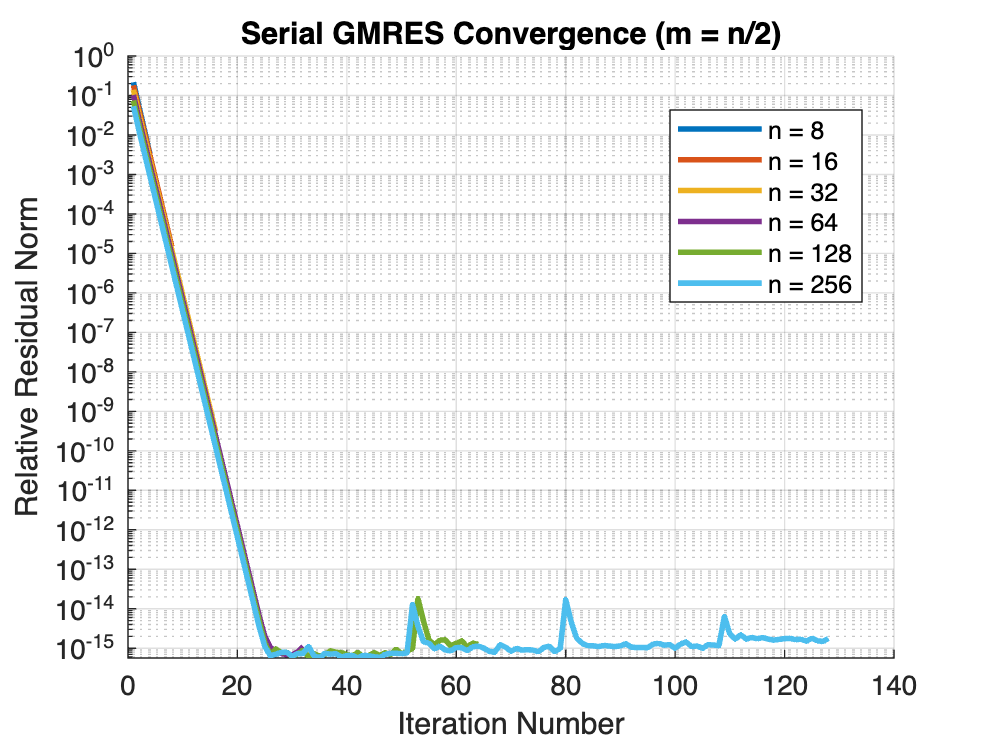


xlabel('Iteration Number');
ylabel('Relative Residual Norm');
title('Serial GMRES Convergence (m = n/2)');
legend(legendEntries, 'Location', 'best');
grid on;
hold off;

% Format the Y-axis tick labels as 10^{−x}
set(gca, 'YScale', 'log');
ax = gca;
ax.YAxis.Exponent = 0;  
yticks(10.^(-16:1:0));  
ytickformat('10^{%g}'); 


% ---------------------------------Local Functions---------------------------------
function [x_approx, residualHistory] = gmresSerial(matrixA, rhsVector, numIterations)
%   Inputs:
%       matrixA      - n x n system matrix.
%       rhsVector    - n x 1 right-hand side vector.
%       numIterations - Number of GMRES iterations to perform.
%
%   Outputs:
%       x_approx       - Approximate solution vector.
%       residualHistory - A vector containing the 2-norm of the residual at each iteration.

    n = length(rhsVector);
    x0 = zeros(n, 1);                 
    r0 = rhsVector - matrixA * x0;   
    beta = norm(r0);

    % If the initial residual is nearly zero, return immediately
    if beta < 1e-15
        x_approx = x0;
        residualHistory = beta;
        return;
    end

    % Call the Arnoldi function defined before
    [Q, H] = arnoldi(matrixA, r0, numIterations);
    residualHistory = zeros(numIterations, 1);

    % Construct the full e1 vector with first element beta
    e1_full = zeros(numIterations+1, 1);
    e1_full(1) = beta;

    % For each iteration k = 1 to numIterations:
    for k = 1:numIterations
        Hk = H(1:k+1, 1:k); % Extract the current Hessenberg matrix Hk (size (k+1) x k) from H.
        Qk = Q(:, 1:k); % Extract the current basis Qk (size n x k) from Q
        e1 = e1_full(1:k+1); % Form the e1 vector for the current iteration
        y = Hk \ e1;  % Solve the least squares problem
        x_approx = x0 + Qk * y; % Update the approximate solution:
        residualHistory(k) = norm(rhsVector - matrixA * x_approx);  % Compute and record the current residual norm
    end
end

### Question03 - Parallel implementation of GMRES

% Define matrix sizes to test.
n_values = [8, 16, 32, 64, 128,256];

% Tolerance for stopping criterion.
tol = 1e-12;

figure;
hold on;
colors = lines(length(n_values)); 
legendEntries = cell(1, length(n_values));

for i = 1:length(n_values)
    n = n_values(i);
    
    % Construct the tridiagonal matrix A:
    main_diag = -4 * ones(n, 1);
    off_diag = ones(n-1, 1);
    matrixA = diag(main_diag) + diag(off_diag, 1) + diag(off_diag, -1);
    b = ((1:n)') / n;
    numIterations = n/2;
    
    % Run the parallel GMRES solver.
    [~, resHist] = gmresParallel(matrixA, b, numIterations, tol);
    
    % Compute the relative residual history: ||r_k||/||b||
    relRes = resHist / norm(b);
    
    % Plot the convergence curve
    semilogy(1:length(relRes), relRes, 'LineWidth', 2, 'Color', colors(i,:));
    legendEntries{i} = sprintf('n = %d', n);
end

Matrix size n = 8, Orthonormality error: 5.408202e-14
Final residual norm: 5.930916e-03, Relative residual: 3.321977e-03

Matrix size n = 16, Orthonormality error: 9.900683e-12
Final residual norm: 3.566626e-05, Relative residual: 1.475407e-05

Matrix size n = 32, Orthonormality error: 4.307914e-07
Final residual norm: 1.046052e-09, Relative residual: 3.129609e-10

-----------Check the stopping criterion-----------------
Matrix size n = 64, Check the stopping criterion 21 itarations
-----------Check the stopping criterion-----------------

Matrix size n = 64, Orthonormality error: 8.067796e-04
Final residual norm: 1.559096e-12, Relative residual: 3.336468e-13

-----------Check the stopping criterion-----------------
Matrix size n = 128, Check the stopping criterion 20 itarations
-----------Check the stopping criterion-----------------

Matrix size n = 128, Orthonormality error: 4.396346e-05
Final residual norm: 5.977373e-12, Relative residual: 9.097657e-13

-----------Check the stoppin

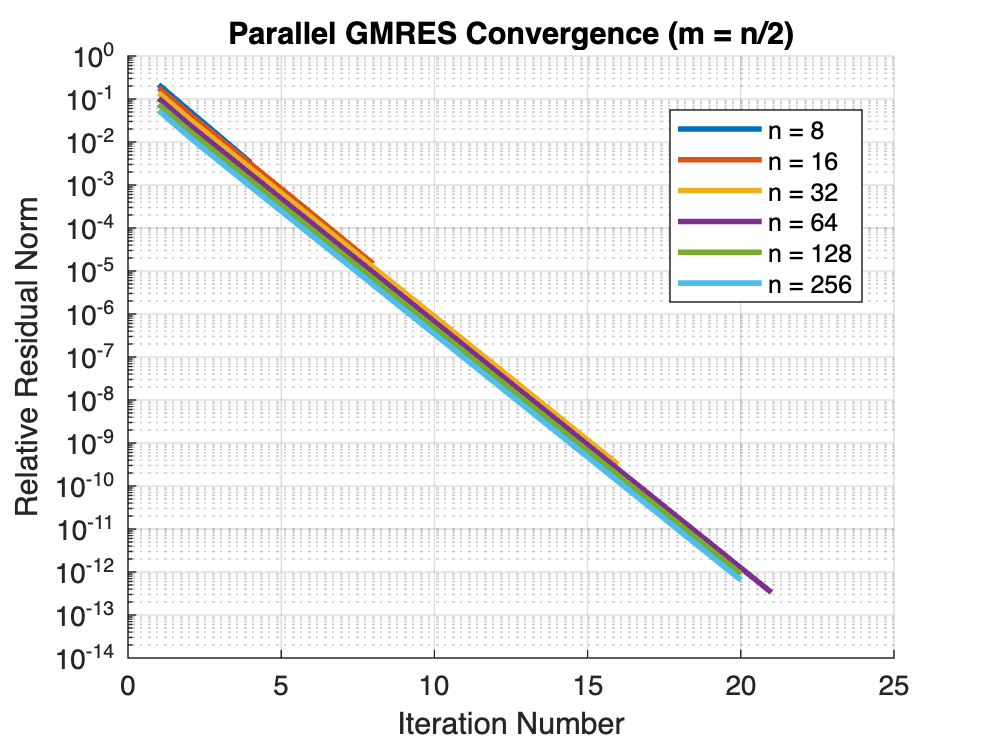


xlabel('Iteration Number');
ylabel('Relative Residual Norm');
title('Parallel GMRES Convergence (m = n/2)');
legend(legendEntries, 'Location', 'best');
grid on;
hold off;

% Format the Y-axis tick labels as 10^{−x}.
set(gca, 'YScale', 'log');
ax = gca;
ax.YAxis.Exponent = 0;  
yticks(10.^(-16:1:0));  
ytickformat('10^{%g}'); 


% ---------------------------------Local Functions---------------------------------
function [x_approx, residualHistory] = gmresParallel(matrixA, rhsVector, numIterations, tol)
% Inputs:
%   matrixA       - n x n system matrix.
%   rhsVector     - n x 1 right-hand side vector.
%   numIterations - Maximum number of GMRES iterations (Krylov subspace dimension).
%   tol           - Tolerance for stopping criterion.
%
% Outputs:
%   x_approx        - Approximate solution vector.
%   residualHistory - Vector containing the 2-norm of the residual at each iteration.


    n = length(rhsVector);
    x0 = zeros(n, 1);                % Initial guess: zero vector
    r0 = rhsVector - matrixA * x0;   % Initial residual
    beta = norm(r0);

    % Early exit if initial residual is already small
    if beta < tol
        x_approx = x0;
        residualHistory = beta;
        return;
    end

    % Initialize Arnoldi iteration variables.
    V = zeros(n, numIterations+1);             % Orthonormal basis matrix
    H = zeros(numIterations+1, numIterations);  % Upper Hessenberg matrix
    V(:,1) = r0 / beta;                        % First basis vector
    residualHistory = zeros(numIterations, 1);  % Preallocate residual history

    % Construct the full e1 vector of size (numIterations+1) with first element beta.
    e1_full = zeros(numIterations+1, 1);
    e1_full(1) = beta;

    % Begin GMRES iteration
    for k = 1:numIterations
        w = matrixA * V(:, k);   % Compute w = A * v_k

        % Compute inner products in parallel
        temp = zeros(k, 1);
        parfor j = 1:k
            temp(j) = V(:, j)' * w;
        end

        % Subtract projections to orthogonalize w against V(:,1:k)
        for j = 1:k
            H(j,k) = temp(j);
            w = w - H(j,k) * V(:, j);
        end
        
        % Compute the norm of the new vector w.
        H(k+1,k) = norm(w);
        if H(k+1,k) < tol
            % If the new vector is nearly zero, a "happy breakdown" occurs.
            numIterations = k;
            fprintf('Matrix size n = %d, happy breakdown: %d\n', n, numIterations);
            break;
        end
        
        
        V(:, k+1) = w / H(k+1,k); % Normalise w to obtain the next basis vector.
        
        % Extract the current Hessenberg matrix and basis for the subspace.
        Hk = H(1:k+1, 1:k);
        Qk = V(:, 1:k);
       
        e1 = e1_full(1:k+1);  % Form the e1 vector for the current subspace.
        y = Hk \ e1; % Solve the least squares problem   
        x_approx = x0 + Qk * y;  % Update the approximate solution.
        residualHistory(k) = norm(rhsVector - matrixA * x_approx);
        
        % Check the stopping criterion (relative residual).
        if (residualHistory(k) / norm(rhsVector)) < tol
            fprintf('-----------Check the stopping criterion-----------------\n');
            fprintf('Matrix size n = %d, Check the stopping criterion %d itarations\n', n, k);
            fprintf('-----------Check the stopping criterion-----------------\n\n');
            break;
        end
    end

    % Trim the residual history vector to the actual number of iterations performed.
    residualHistory = residualHistory(1:k);

    % ----- Correctness Tests -------
    % 1. Orthonormality Check: Q should be nearly orthonormal.
    orthoError = norm(V(:,1:k+1)' * V(:,1:k+1) - eye(k+1));
    fprintf('Matrix size n = %d, Orthonormality error: %e\n', n, orthoError);
    
    % 2. Final Residual Check: Print final absolute and relative residual.
    finalResidual = norm(rhsVector - matrixA * x_approx);
    relResidual = finalResidual / norm(rhsVector);
    fprintf('Final residual norm: %e, Relative residual: %e\n\n', finalResidual, relResidual);

end